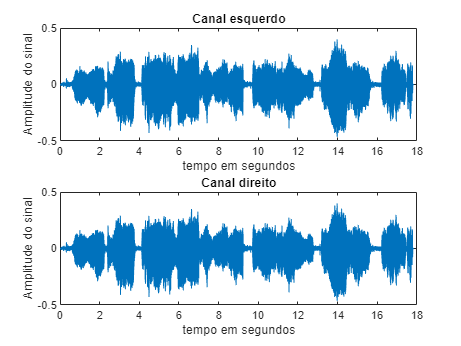

[Y, FS] = audioread('2 - Fourier_Vogais_Audio1860.wav');

TS = 1/FS;
Npontos = length(Y);
Vfinal = (Npontos-1)*TS;

tempo = linspace(0,Vfinal,Npontos);

figure(1)
subplot(2,1,1)
plot(tempo,Y(:,1))
xlabel('tempo em segundos')
ylabel('Amplitude do sinal')
title('Canal esquerdo')

subplot(2,1,2)
plot(tempo,Y(:,2))
xlabel('tempo em segundos')
ylabel('Amplitude do sinal')
title('Canal direito')

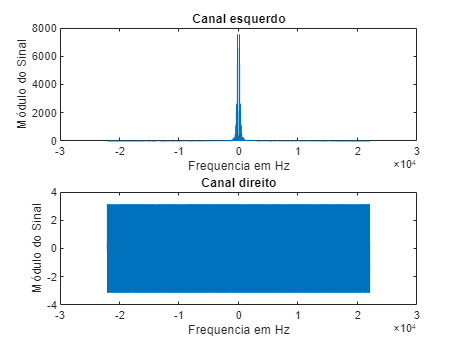


sound(Y,FS);
FY = fftshift(fft(Y));

frequencia = linspace(-FS/2,FS/2,Npontos);

figure(2)

subplot(2,1,1)
plot(frequencia,abs(FY(:,1)))
xlabel('Frequencia em Hz')
ylabel('Módulo do Sinal')
title('Canal esquerdo')

subplot(2,1,2)
plot(frequencia,angle(FY(:,1)))
xlabel('Frequencia em Hz')
ylabel('Módulo do Sinal')
title('Canal direito')